# Taylorentwicklung

In diesem Programm wird die Taylorentwicklung  interaktiv präsentiert. 

Als Bespiele werden die Funktionen

           
$$f(x)=e^x, $$


          
$$f(x)=x \sin(x),
$$


         $f(x)=\frac{x^3}{2+x^4}$,

auf einem Intervall $I=[c,d]$ betrachtet. Die Stelle $a \in I$, an der die Taylor-Approximation $p_n$ vom Grad $n$ bestimmt werden soll, kann frei  gewählt werden.  Das Polynom $p_n$ wird gezeigt und der Fehler $\max_{x \in I}|f(x)-p_n(x)|$ wird bestimmt.

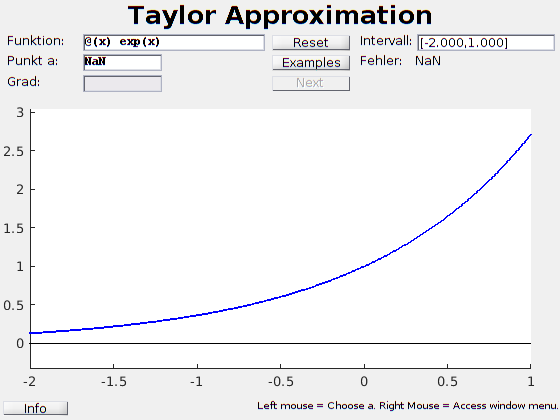

TCM_taylor_approximation

# Aktivität:

 -  wählen Sie eins der Beispiele

 -  wählen Sie einen Punkt $a \in I$

  - wählen Sie den Polynomgrad

Das Taylorpolynom wird gezeigt. Falls  Grad $n \geq 1$gilt, werden die Polynome $p_n$ und $p_{n-1}$ gezeigt.

Sie können den Grad ändern (ein neuer Wert eintragen oder "Next" verwenden).

Sie können das Intervall $I$ und die Stelle $a \in I$ varieren.

Unterstehendes MATLAB-Program **TCM_taylor_approximation** wurde an der Uni-Stuttgart im Rahmen des Projektes ``Teaching Calculus mit MATLAB'' entwickelt, siehe [https://pnp.mathematik.uni-stuttgart.de/imng/TCM/.](https://pnp.mathematik.uni-stuttgart.de/imng/TCM/.)

function TCM_taylor_approximation

% TCM_TAYLOR_APPROXIMATION Interactive illustration of the approximation 
% by a Taylor polynom.
%
%   TCM_TAYLOR_APPROXIMATION illustrates the interpolation of a function  
%   y = f(x) at a point a including its derivatives up to order n by
%   the Taylor polynomial of order n. In addition, the error on a prescribed interval 
%   is computed. 
%
%   EXAMPLES
%
%   Basic example: For the exponential function, all derivatives are equal. Hence, this standard 
%   example provides a very simple illustration of Taylor approximations. 
%
%   Sine: The sine function is approximated quite well on small intervals, while for 
%   larger intervals accurate approximations require very high degree.
% 
%   Rational function: For a rational function, the approximation error tends to zero inside
%   the radius of convergence, but becomes arbitrarily large ouside. 
%
%   To investigate other cases, insert a function in the corresponding field.
%   However, note that either the Symbolic Math Toolbox, the Matlab Toolbox for MATLAB or
%   the <a href="http://www.mathworks.com/matlabcentral/fileexchange/61849-autodiff-r2016b">AutoDiff</a> Toolbox have to be installed to run this demo.
%
%   TCM_TAYLOR_APPROXIMATION is part of the <a href="http://www2.imng.uni-stuttgart.de/LstNumGeoMod/TCM/">TCM</a> project.
%   Related course materials can be found at <a href="http://www.mathematics-online.org/inhalt/aussage/aussage178/">Mathematics Online</a>.

% Authors: Florian Martin, Lars von Wolff
% Last updated: 04.08.2016

% Initialize data
TCM_Data.move = 0;
TCM_Data.fun = @(x) exp(x);  
TCM_Data.funstring = '@(x) exp(x)';
TCM_Data.a = NaN;
TCM_Data.n = 0;

% Do not delete these Variables
TCM_Data.plot_window = [-2 1 0 3];
TCM_Data.LmbMenuString = '';
TCM_Data.examples = {'Exp-Funktion','Sinus','Rationale Funktion'};

% Layout:
% ---------------------------------------
% |               Title                 |
% | ------------ --------- ------------ |
% | | Settings | |Buttons| | Feedback | |
% | ------------ --------- ------------ |
% | ----------------------------------- |
% | |           Axis (Plot)           | |
% | ----------------------------------- |
% | Info-Button         Hint            |
% ---------------------------------------
% Initialize Layout:
TCM_UI.TitleHeightMin = 10;        % minimal height of the title
TCM_UI.TitleHeightMax = 32;        % maximal height of the title
TCM_UI.HintHeightMin = 8;          % minimal height of the hint
TCM_UI.HintHeightMax = 15;         % maximal height of the hint
TCM_UI.SettingsHeightMin = 40;     % minimal height of the feedback, buttons and 
                                   % setting panel
TCM_UI.SettingsHeightMax = 70;     % maximal height of the feedback, buttons and 
                                   % setting panel
TCM_UI.SettingsRatio = 4.5;          % aspect ratio of the settings  
                                   % (increase if more settings needed)
TCM_UI.ButtonsRatio = 1.4;         % aspect ratio of the Buttons panel
TCM_UI.FeedbackRatio = 3.4;        % aspect ratio of the feedback
TCM_UI.AxisHeightTarget = 0.73;    % desired fraction of figure 
                                   % used for the plot
TCM_UI.InfoPortion = 1/8;          % Portion of the Info Button in the last  
                                   % line 
TCM_UI.Title = 'Taylor Approximation';
TCM_UI.mono = get(0,'FixedWidthFontName');
% Strings for generating the information window
TCM_UI.Author = 'F. Martin and L. von Wolff';
TCM_UI.Date = '04.08.2016';
TCM_UI.Web = 'http://www.mathematics-online.org/inhalt/aussage/aussage178/';
      
CreateUI();

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% UI-Elements in Settings %%%%%%%%%%%%%%%%%%%%
% Text for Function
TCM_UI.funtext = uicontrol('Units','normalized','Parent',TCM_UI.settingspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontUnits','normalized','FontSize',0.67,...
        'HorizontalAlignment','left', ...
	'Position',[.01,.70,.29,.30],...
	'String','Funktion:',...
	'Style','text');

% Input for Function
TCM_UI.funinput=uicontrol('Units','normalized', 'Parent',TCM_UI.settingspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontWeight','bold',...
        'FontUnits','normalized','FontSize',0.65,'FontName',TCM_UI.mono,...
        'HorizontalAlignment','left', ...
	'Position',[.30,.70,.69,.30],...
	'String','',...
	'Style','edit',...
	'Callback',@function_update);

% Text for point 
TCM_UI.pointtext = uicontrol('Units','normalized', 'Parent',TCM_UI.settingspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontUnits','normalized','FontSize',0.67,...
        'HorizontalAlignment','left', ...
	'Position',[.01,.35,.29,.30],...
	'String','Punkt a:',...
	'Style','text');

% Input point
TCM_UI.pointinput=uicontrol('Units','normalized', 'Parent',TCM_UI.settingspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontWeight','bold',...
        'FontUnits','normalized','FontSize',0.65,'FontName',TCM_UI.mono,...
        'HorizontalAlignment','left', ...
	'Position',[.30,.35,.3,.30],...
	'String','NaN',...
	'Style','edit','Callback',@point_update);

% Text for degree 
TCM_UI.degreetext = uicontrol('Units','normalized', 'Parent',TCM_UI.settingspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontUnits','normalized','FontSize',0.67,...
        'HorizontalAlignment','left', ...
	'Position',[.01,.00,.3,.30],...
	'String','Grad:',...
	'Style','text');

% Input degree
TCM_UI.degreeinput=uicontrol('Units','normalized', 'Parent',TCM_UI.settingspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontWeight','bold',...
        'FontUnits','normalized','FontSize',0.65,'FontName',TCM_UI.mono,...
        'HorizontalAlignment','left', ...
	'Position',[.30,.00,.3,.30],...
	'String','NaN',...
	'Style','edit','Callback',@degree_update,...
    'Enable','Off');

%%%%%%%%%%%%%%%%%%%%%%%%% UI-Elements in Buttons Panel %%%%%%%%%%%%%%%%%%%%
% Reset-Button
TCM_UI.reset=uicontrol('Units','normalized','Parent',TCM_UI.buttonspanel, ...
	'BackgroundColor',get(gcf,'Color'), ...
	'String','Reset', ...
    'FontUnits','normalized','FontSize',0.7,...
	'Position',[.01,.70,.98,.30], ...
	'Callback',@reset,...
	'Style','pushbutton');

% Example button
TCM_UI.examples=uicontrol('Units','normalized','Parent',TCM_UI.buttonspanel, ...
	'BackgroundColor',get(gcf,'Color'), ...
	'String','Examples', ...
    'FontUnits','normalized','FontSize',0.7,...
	'Position',[.01,.35,.98,.30], 'Callback',@OpenExampleMenu,...
	'Style','pushbutton');

% Next-Button
TCM_UI.next=uicontrol('Units','normalized','Parent',TCM_UI.buttonspanel, ...
	'BackgroundColor',get(gcf,'Color'), ...
	'String','Next', ...
    'FontUnits','normalized','FontSize',0.7,...
	'Position',[.01,.0,.98,.30], ...
	'Callback',@next,...
	'Style','pushbutton','Enable','Off');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% UI-Elements in Feedback %%%%%%%%%%%%%%%%%%%%

% Text for interval
TCM_UI.intervaltext=uicontrol('Units','normalized','Parent',TCM_UI.feedbackpanel,...
        'BackgroundColor',get(gcf,'Color'), ...
        'HorizontalAlignment','left', ...
        'FontUnits','normalized','FontSize',0.7,...
	'Position',[.01,.7,.29,.3],...
	'String',sprintf('Intervall:'),...
	'Style','text');

% Input interval
TCM_UI.intervalinput=uicontrol('Units','normalized','Parent',TCM_UI.feedbackpanel,...
        'BackgroundColor',get(gcf,'Color'), ...
        'HorizontalAlignment','left', ...
        'FontUnits','normalized','FontSize',0.7,...
	'Position',[.30,.7,.69,.3],...
	'String','[NaN,NaN]',...
	'Style','edit',...
    'Callback',@interval_update);

% Text for error
TCM_UI.errortext=uicontrol('Units','normalized','Parent',TCM_UI.feedbackpanel,...
        'BackgroundColor',get(gcf,'Color'), ...
        'HorizontalAlignment','left', ...
        'FontUnits','normalized','FontSize',0.7,...
	'Position',[.01,.35,.9,.3],...
	'String','Fehler: NaN',...
	'Style','text');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% UI-Elements in Axis %%%%%%%%%%%%%%%%%%%%%%%%
TCM_UI.ax=axes('Position',[.05,.1,.9,.85],'Parent',TCM_UI.axispanel);
axis(TCM_UI.ax,'equal');
TCM_UI.modification = uicontextmenu('Callback',@reset_zoom_limits); 
TCM_UI.mpan = uimenu('Parent',TCM_UI.modification,'Label','Enable pan',...
        'Callback',@axis_context);
TCM_UI.mzoomi = uimenu('Parent',TCM_UI.modification,'Label','Enable zoom in',...
    'Callback',@axis_context); 
TCM_UI.mzoomo = uimenu('Parent',TCM_UI.modification,'Label','Enable zoom out',...
        'Callback',@axis_context); 
TCM_UI.ax.UIContextMenu = TCM_UI.modification;

% functions for smoothless zooming and panning
panfun = pan(TCM_UI.fig);
panfun.UIContextMenu = TCM_UI.modification;
set(panfun,'ActionPostCallback',@pan_modify);
zoomfun = zoom(TCM_UI.fig);
zoomfun.UIContextMenu = TCM_UI.modification; 
set(zoomfun,'ActionPostCallback',@zoom_modify);
set(zoomfun,'ButtonDownFilter',@set_zoom_limits);
set(zoomfun,'RightClickAction','PostContextMenu');
set(findall(TCM_UI.fig,'tag','Exploration.Pan'),'enable','off');
set(findall(TCM_UI.fig,'tag','Exploration.ZoomOut'),'enable','off');
set(findall(TCM_UI.fig,'tag','Exploration.ZoomIn'),'enable','off');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Start the program %%%%%%%%%%%%%%%%%%%%%%%%%%
changeexample(1);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%% Callback functions %%%%%%%%%%%%%%%%%%%%%%%%%%%

% new function input
function function_update(varargin)
TCM_Data.funstring = get(TCM_UI.funinput,'String');
var = TCM_Data.funstring(find(TCM_Data.funstring=='(',1)+1:...
    find(TCM_Data.funstring==')',1)-1);
TCM_Data.fun = eval([TCM_Data.funstring '+0*' var]);
TCM_Data.plot_window(1:2) = [-2 2];
compute_window
reset;
end

% calculate y-range depending von the size of the function
function compute_window
x = linspace(TCM_Data.plot_window(1),TCM_Data.plot_window(2),1000);
fmin = min(TCM_Data.fun(x));
fmax = max(TCM_Data.fun(x));
dy = fmax-fmin;   
if abs(dy) < 10^-8
    TCM_Data.plot_window(3) = min(fmin-1,-1);
    TCM_Data.plot_window(4) = max(fmax+1,1);
else
    TCM_Data.plot_window(3:4) = [min(-dy/8,fmin-dy/8), max(dy/8,fmax+dy/8)];
end
end

% point input
function point_update(varargin)
set(TCM_UI.degreeinput,'Enable','On');
TCM_Data.a = str2double(get(TCM_UI.pointinput,'String'));
if TCM_Data.a < TCM_Data.plot_window(1) || TCM_Data.a > TCM_Data.plot_window(2)
    TCM_Data.plot_window(1:2) = TCM_Data.a + [-2 2];
    compute_window;
end
TCM_UI.next.Enable = 'On';
myplot;
end

% degree input
function degree_update(varargin)
n = str2double(get(TCM_UI.degreeinput,'String'));
if n > 20
    n = 20;
end
if n>TCM_Data.n && ~isnan(TCM_Data.a) 
   derivatives([TCM_Data.n+1,n]);
end
if isnan(n)
    TCM_Data.n = -1;
else
    TCM_Data.n = n;
end
myplot;
end

% interval input
function interval_update(varargin)
TCM_Data.plot_window(1:2) = eval(get(TCM_UI.intervalinput,'String'));
compute_window
myplot;
end

% refresh all data from UI
function reset(varargin)
set(TCM_UI.degreeinput,'Enable','Off');
set(TCM_UI.errortext,'String','Fehler: NaN');
TCM_UI.next.Enable = 'Off';
TCM_Data.a = NaN;
TCM_Data.n = -1;
window_disable.Label = 'Disable pan';
axis_context(window_disable);
myplot;
end

% button next pressed
function next(varargin)
if ~isnan(TCM_Data.a) && TCM_Data.n < 20
   derivatives([TCM_Data.n+1, TCM_Data.n+1]);
   TCM_Data.n = TCM_Data.n+1;
end
myplot;
end

% moving the mouse in the axis
function myMovefct(varargin)
if TCM_Data.move
    p = getClickPosition(TCM_UI.ax);
    if(~isnan(p))
        TCM_Data.a = p(1);
        set(TCM_UI.pointinput,'String',num2str(TCM_Data.a)); 
        myplot;
    end
end
end

% releasing a mouse button
function myUpfct(varargin)
TCM_Data.move = 0;
myplot;
end

% This function is called when the mouse button is clicked in the GUI.
function myDownfct(varargin)
p = getClickPosition(TCM_UI.ax);
if isnan(p)
    return
end
if isnan(TCM_Data.a) && strcmp(get(gcf,'SelectionType'),'normal');
    TCM_Data.a = p(1);
    set(TCM_UI.pointinput,'String',num2str(TCM_Data.a));
    set(TCM_UI.degreeinput,'Enable','On');
    TCM_UI.next.Enable = 'On';
    myplot;
elseif ~isnan(TCM_Data.a) && strcmp(get(gcf,'SelectionType'),'normal');
    dist = norm(window_transformation(p)-window_transformation(...
       [TCM_Data.a; 0]),2);
   if dist < 0.05
       TCM_Data.a = p(1);
       set(TCM_UI.pointinput,'String',num2str(TCM_Data.a));    
       TCM_Data.move = 1;
       myplot;
   end
end
UpdateHinttext;
end

% transformation to a square unit window
function p = window_transformation(p)
ax_pos = TCM_UI.ax.Position;
p = [ax_pos(3)/(TCM_Data.plot_window(2)-TCM_Data.plot_window(1)) 0;...
    0 ax_pos(4)/(TCM_Data.plot_window(4)-TCM_Data.plot_window(3))] *...
    (p(:) - [TCM_Data.plot_window(1); TCM_Data.plot_window(3)]);
end

function p = getClickPosition(myaxes)
x = get(myaxes,'xlim');
y = get(myaxes,'ylim');
newpoint=get(myaxes,'CurrentPoint');
if (newpoint(1) < x(1) || newpoint(1) > x(2) || ...
    newpoint(3) < y(1) || newpoint(3) > y(2))
    p = NaN;
else
    p = newpoint([1 3]);
end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% kernel functions %%%%%%%%%%%%%%%%%%%%%%%%%%%
% compute derivatives 
function derivatives(nrange) 
v = ver;
if exist('ainit','file')
    if nrange(1)==0 
       TCM_Data.f{1} = TCM_Data.fun;
    end
    for n=max(nrange(1),1):nrange(2)
       TCM_Data.f{n+1} = adiff(TCM_Data.f{1},n); 
    end    
elseif exist('maple','file')    
    xsym = sym('x','real');
    % we have to recalculate all derivatives due to some limitation of the
    % Maple Toolbox, so we set nrange(1) to 0.
    nrange(1)=0;
    if nrange(1)==0 
       f = TCM_Data.fun(xsym);
       TCM_Data.f{1} = f;
    end
    for n=max(nrange(1),1):nrange(2)
       df = diff(TCM_Data.f{n},xsym);
       TCM_Data.f{n+1} = df;
    end
elseif any(strcmp('Symbolic Math Toolbox', {v.Name}))    
    xsym = sym('x','real'); 
    if nrange(1)==0 
       f(xsym) = TCM_Data.fun(xsym);
       TCM_Data.f{1} = f;
    end
    for n=max(nrange(1),1):nrange(2)
       df = diff(TCM_Data.f{n},xsym);
       TCM_Data.f{n+1} = df; 
    end
else
    disp('Please install either the Symbolic Math Toolbox, Maple Toolbox or the AutoDiff Toolbox.');
    close gcf;
end
end

% plot function
function myplot
try
    subplot(TCM_UI.ax)
catch
    return
end
cla reset; hold on

h = TCM_Data.plot_window(2) - TCM_Data.plot_window(1);
x = linspace(TCM_Data.plot_window(1)-h,TCM_Data.plot_window(2)+h,1000);
fx = TCM_Data.fun(x);
plot(x,fx,'b','LineWidth',2);
plot([x(1) x(end)],[0 0],'k');

% plot the point
if ~isnan(TCM_Data.a);
    a = TCM_Data.a;
    f0 = TCM_Data.fun(a);
    if isnan(f0)
        f0 = hospital(0);
    end
    plot(a,f0,'or');
    plot(a,0,'+black');
    plot(a,0,'or');
    plot(a*[1 1],[0 f0],':r','LineWidth',1.5);
    text(a,0,'a','VerticalAlignment','Top','Clipping','on');
end

% plot the Taylor polynomials
if TCM_Data.n >=0
    % compute the Taylor coefficients
    c = zeros(1,TCM_Data.n+1);
    for n=0:TCM_Data.n
        try
            c(n+1) = TCM_Data.f{n+1}(TCM_Data.a)/factorial(n);
            if isnan(c(n+1))
                error('false computation');
            end
        catch
            c(n+1) = hospital(n)/factorial(n);       
        end
    end
   
    % plot lower order
    if n > 0
        px = polyval(c(TCM_Data.n:-1:1),x-a);
        plot(x,px,'Color',[0 0.5 0]);
    end

    % plot highest order
    px = polyval(c(end:-1:1),x-a);
    plot(x,px,'Color',[0 0.5 0],'LineWidth',2);
end

xlim([TCM_Data.plot_window(1) TCM_Data.plot_window(2)]);
ylim([TCM_Data.plot_window(3) TCM_Data.plot_window(4)]);

set(TCM_UI.pointinput,'String',sprintf('%.3f',TCM_Data.a));
if TCM_Data.n ~= -1
    set(TCM_UI.degreeinput,'String',sprintf('%d',TCM_Data.n)); 
else
    set(TCM_UI.degreeinput,'String',''); 
end
set(TCM_UI.intervalinput,'String',['[' sprintf('%.3f',TCM_Data.plot_window(1)) ...
    ',' sprintf('%.3f',TCM_Data.plot_window(2)) ']']);

set(TCM_UI.funinput,'String',sprintf(TCM_Data.funstring));

if TCM_Data.n > -1
    ind = (x >= TCM_Data.plot_window(1)) & (x <= TCM_Data.plot_window(2));
    err = norm(fx(ind)-px(ind),inf);
else
    err = NaN;
end
set(TCM_UI.errortext,'String',sprintf('Fehler: %5.3e',err));

SetWindowLimits
UpdateHinttext
end

function y = hospital(n)
if n==0
    derivatives([0 0]);
end
v = ver;
if exist('ainit','file') 
    x0 = ainit(TCM_Data.a,n+2);
    y = TCM_Data.fun(x0);
    if isnan(y{n})
        error('Too many calculations with the rule of l''Hospital needed. Change the point.');
    else
        y = y{n};
    end
elseif exist('maple','file') 
    xsym = sym('x','real');
    try
        y = limit(TCM_Data.f{n+1},TCM_Data.a);
    catch
        error('No limit of the function/derivative can be calculated at the chosen point x0.');
    end
else any(strcmp('Symbolic Math Toolbox', {v.Name})) 
    xsym = sym('xsym','real');
    try
        y = limit(TCM_Data.f{n+1}(xsym),xsym,TCM_Data.a);
    catch
        error('No limit of the function/derivative can be calculated at the chosen point x0.');
    end
end
end


% Update the Hinttext
function UpdateHinttext
if isnan(TCM_Data.a)
    LmbString = 'Left mouse = Choose a. ';
elseif TCM_Data.n == -1
    LmbString = 'Left mouse = Move a, Next = Set degree to 0. ';
else
    LmbString = 'Left mouse = Move a, Next = Increase degree. ';
end    
if(numel(TCM_Data.LmbMenuString) == 0)
    set(TCM_UI.hinttext,'String',[LmbString 'Right Mouse = Access window menu.']);
else
    set(TCM_UI.hinttext,'String',[TCM_Data.LmbMenuString 'Right Mouse = Access window menu.']);
end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%% example functions %%%%%%%%%%%%%%%%%%%%%%%%%%%

function CreateExampleMenu
TCM_UI.UICexamples = uicontextmenu;
for i=1:numel(TCM_Data.examples)
    uimenu('Parent',TCM_UI.UICexamples,'Label',TCM_Data.examples{i},'Callback',{@changeexample,i});
end
end

function OpenExampleMenu(varargin)
TCM_UI.examples.Units = 'pixels';
TCM_UI.buttonspanel.Units = 'pixels';
TCM_UI.UICexamples.Position = TCM_UI.examples.Position(1:2) + TCM_UI.buttonspanel.Position(1:2);
TCM_UI.examples.Units = 'normalized';
TCM_UI.buttonspanel.Units = 'points';
TCM_UI.UICexamples.Visible = 'on';
end
 
              
function changeexample(varargin)  
switch varargin{numel(varargin)}
    case 1
        set(TCM_UI.funinput,'String','@(x) exp(x)'); 
        function_update;
        set(TCM_UI.intervalinput,'String','[-2 1]');
        interval_update;
        TCM_UI.next.Enable = 'Off';
    case 2
        set(TCM_UI.funinput,'String','@(x) x.*sin(x)'); 
        function_update;
        TCM_Data.a = pi;
        set(TCM_UI.intervalinput,'String','[0 2*pi]');
        interval_update;
        set(TCM_UI.degreeinput,'String','4');
        degree_update;
        TCM_UI.degreeinput.Enable = 'On';
        TCM_UI.next.Enable = 'On';
    case 3
        set(TCM_UI.funinput,'String','@(x) x.^3./(2+x.^4)'); 
        function_update;
        TCM_Data.a = 1/2;
        set(TCM_UI.intervalinput,'String','[-2 2]');
        interval_update;
        set(TCM_UI.degreeinput,'String','5');
        degree_update;
        TCM_UI.degreeinput.Enable = 'On';
        TCM_UI.next.Enable = 'On';
end
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% zoom functions %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% function for updating the internal plot window
function zoom_modify(varargin)
if max(abs(TCM_Data.plot_window-axis(TCM_UI.ax)))< 10^-10
    ZoomOut;
end
pan_modify;
end

function pan_modify(varargin)
TCM_Data.plot_window = axis(TCM_UI.ax);
myplot;
end

% functions for proper zooming in (prevent double-click zoom out)
function [flag] = set_zoom_limits(varargin)
if(strcmp(TCM_UI.fig.SelectionType,'open'))
    flag = true;
else
    flag = false;
end
end

function reset_zoom_limits(varargin)
SetWindowLimits;
end

% handling the axis context menu
function axis_context(varargin)
zoom(TCM_UI.fig, 'off'); pan(TCM_UI.fig, 'off');
mode_strings = {'pan','zoom in','zoom out'};
status_strings = {'Enable ','Disable '};
switch varargin{1}.Label(1:7)
    case 'Enable '
        mode = strcmp(varargin{1}.Label(8:end),mode_strings);
        TCM_Data.LmbMenuString = ['Left Mouse = ' mode_strings{mode} ' the window. '];
        set(TCM_UI.mpan,'Label',horzcat(status_strings{mode(1)+1},mode_strings{1}));
        set(TCM_UI.mzoomi,'Label',horzcat(status_strings{mode(2)+1},mode_strings{2}));
        set(TCM_UI.mzoomo,'Label',horzcat(status_strings{mode(3)+1},mode_strings{3}));
        split_mode = strsplit(mode_strings{mode},' ');
        if numel(split_mode) == 1
            pan(TCM_UI.fig, 'on');
        else
            zoomh = zoom(TCM_UI.fig);
            zoomh.Enable = 'on';
            zoomh.Direction = split_mode{2};
        end
    case 'Disable'
        TCM_Data.LmbMenuString = '';
        set(TCM_UI.mpan,'Label','Enable pan');
        set(TCM_UI.mzoomi,'Label','Enable zoom in');
        set(TCM_UI.mzoomo,'Label','Enable zoom out');     
end
UpdateHinttext;
end

function SetWindowLimits
ZoomOut;
xlim(TCM_UI.ax,[TCM_Data.plot_window(1) TCM_Data.plot_window(2)]);
ylim(TCM_UI.ax,[TCM_Data.plot_window(3) TCM_Data.plot_window(4)]);
end

function ZoomOut
hx = TCM_Data.plot_window(2) - TCM_Data.plot_window(1);
hy = TCM_Data.plot_window(4) - TCM_Data.plot_window(3);
xlim(TCM_UI.ax,[TCM_Data.plot_window(1)-hx/2 TCM_Data.plot_window(2)+hx/2]);
ylim(TCM_UI.ax,[TCM_Data.plot_window(3)-hy/2 TCM_Data.plot_window(4)+hy/2]);
zoom(TCM_UI.fig, 'reset');
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% layout functions %%%%%%%%%%%%%%%%%%%%%%%%%%%

% functions for creating the different UI-Parts and managing the resize of
% the window
function CreateUI
TCM_UI.fig = figure('Visible','off', 'Units','points','Toolbar','none',...
    'SizeChangedFcn',@calculate_layout, 'WindowButtonDownFcn',@myDownfct,'WindowButtonMotionFcn',...
    @myMovefct,'WindowButtonUpFcn',@myUpfct,'numbertitle','off','name',TCM_UI.Title);
TCM_UI.titletext = uicontrol('Units','points','BackgroundColor',TCM_UI.fig.Color, ...
	'HorizontalAlignment','center',  'FontWeight','bold', ...
    'FontUnits','normalized',        'FontSize',0.8,...
	'String',TCM_UI.Title,        'Style','text');
TCM_UI.hinttext = uicontrol('Units','points','BackgroundColor',TCM_UI.fig.Color, ...
    'HorizontalAlignment','right',...
    'FontUnits','normalized',        'FontSize',0.63,...
	'String','','Style','text');
TCM_UI.infobutton=uicontrol('Units','points', ...
	'BackgroundColor',TCM_UI.fig.Color, ...
	'String','Info', 'HorizontalAlignment','left',...
    'FontUnits','normalized','FontSize',0.7,...
	'Callback',@information,'Style','pushbutton');
TCM_UI.feedbackpanel = uipanel('Units','points','BackgroundColor',TCM_UI.fig.Color,'BorderType','none');
TCM_UI.buttonspanel = uipanel('Units','points','BackgroundColor',TCM_UI.fig.Color,'BorderType','none');
TCM_UI.settingspanel = uipanel('Units','points','BackgroundColor',TCM_UI.fig.Color,'BorderType','none');
TCM_UI.axispanel = uipanel('Units','points','BackgroundColor',TCM_UI.fig.Color,'BorderType','none');
CreateExampleMenu
TCM_UI.fig.Visible= 'on';
end


function calculate_layout(varargin) 
figpos = TCM_UI.fig.Position;
WMax = TCM_UI.SettingsHeightMax*(TCM_UI.SettingsRatio + TCM_UI.FeedbackRatio + TCM_UI.ButtonsRatio);
WMin = TCM_UI.SettingsHeightMin*(TCM_UI.SettingsRatio + TCM_UI.FeedbackRatio + TCM_UI.ButtonsRatio);
HMax = TCM_UI.TitleHeightMax + TCM_UI.HintHeightMax;
HMin = TCM_UI.TitleHeightMin + TCM_UI.HintHeightMin;

wratio = max(0,min(1,(min(figpos(3),1.3*figpos(4))-WMin)/(WMax-WMin)));
XCoords = [1,0,0,0,0,0,0,figpos(3)];
SWidth =      wratio*TCM_UI.SettingsHeightMax*TCM_UI.SettingsRatio...
        + (1-wratio)*TCM_UI.SettingsHeightMin*TCM_UI.SettingsRatio;
BWidth =      wratio*TCM_UI.SettingsHeightMax*TCM_UI.ButtonsRatio...
        + (1-wratio)*TCM_UI.SettingsHeightMin*TCM_UI.ButtonsRatio; 
FWidth =      wratio*TCM_UI.SettingsHeightMax*TCM_UI.FeedbackRatio...
        + (1-wratio)*TCM_UI.SettingsHeightMin*TCM_UI.FeedbackRatio; 
RemWidth = figpos(3)-3-SWidth-FWidth-BWidth;
XCoords(2) = max(1,0.3*RemWidth);
XCoords(3) = XCoords(2) + 1 + SWidth;
XCoords(4) = XCoords(3) + max(0,0.2*RemWidth);
XCoords(5) = XCoords(4) + 1 + BWidth;
XCoords(6) = XCoords(5) + max(0,0.2*RemWidth);
XCoords(7) = XCoords(6) + 1 + FWidth;
SHeight = wratio*TCM_UI.SettingsHeightMax + (1-wratio)*TCM_UI.SettingsHeightMin;
if(HMin > min(figpos(4),0.9*figpos(3))*(1-TCM_UI.AxisHeightTarget)-5-SHeight)
    hratio = 0;
elseif(HMax <  min(figpos(4),0.9*figpos(3))*(1-TCM_UI.AxisHeightTarget)-5-SHeight)
    hratio = 1;
else
    hratio = (( min(figpos(4),0.9*figpos(3))*(1-TCM_UI.AxisHeightTarget)-5-SHeight)  -HMin)/(HMax-HMin);
end
YCoords = [1,0,0,0,figpos(4)-1];
YCoords(2) = YCoords(1) + 1 + hratio*TCM_UI.HintHeightMax     + (1-hratio)*TCM_UI.HintHeightMin;
YCoords(4) = YCoords(5) - 1 - hratio*TCM_UI.TitleHeightMax    - (1-hratio)*TCM_UI.TitleHeightMin;
YCoords(3) = YCoords(4) - 1 - SHeight;
TCM_UI.titletext.Position =     [XCoords(1)+1,  YCoords(4)+1,  XCoords(8)-XCoords(1)-1,  YCoords(5)-YCoords(4)-1];
TCM_UI.settingspanel.Position = [XCoords(2)+1,  YCoords(3)+1,  XCoords(3)-XCoords(2)-1,  YCoords(4)-YCoords(3)-1];
TCM_UI.buttonspanel.Position =  [XCoords(4)+1,  YCoords(3)+1,  XCoords(5)-XCoords(4)-1,  YCoords(4)-YCoords(3)-1];
TCM_UI.feedbackpanel.Position = [XCoords(6)+1,  YCoords(3)+1,  XCoords(7)-XCoords(6)-1,  YCoords(4)-YCoords(3)-1];
TCM_UI.axispanel.Position =     [XCoords(1)+1,  YCoords(2)+1,  XCoords(8)-XCoords(1)-1,  max(0,YCoords(3)-YCoords(2)-1)];
TmpXCoord = TCM_UI.InfoPortion*(XCoords(8)-XCoords(1)-1);
TCM_UI.infobutton.Position =    [XCoords(1)+1,  YCoords(1)+1,  TmpXCoord-XCoords(1)-1,   YCoords(2)-YCoords(1)-1];
TCM_UI.hinttext.Position =      [TmpXCoord+1,   YCoords(1)+1,  XCoords(8)-TmpXCoord-1,   YCoords(2)-YCoords(1)-1];
end

% function for opening the information webpage
function information(varargin)
pos = TCM_UI.fig.OuterPosition;
infodialog = dialog('Name','Information','Units','points',...
    'OuterPosition',[pos(1)+pos(3)/4 pos(2)+pos(4)/4 pos(3)/2 pos(4)/2]);
uicontrol('Units','normalized', 'Parent',infodialog, ...
        'FontUnits','normalized', 'FontSize',0.67,...
        'HorizontalAlignment','center', 'Position',[.01,.6,.98,.15],...
	'String','Mathematics Online Link', 'Style','text',...
    'ForegroundColor','blue','ButtonDownFcn',@linkfun,...
    'Enable','inactive');
uicontrol('Units','normalized', 'Parent',infodialog, ...
        'FontUnits','normalized', 'FontSize',0.4,...
        'HorizontalAlignment','center', 'Position',[.01,.4,.98,.15],...
	'String',{horzcat('Created by ',TCM_UI.Author,'.');horzcat('Version: ',TCM_UI.Date)} , 'Style','text');
end

function linkfun(varargin)
web(TCM_UI.Web)
end
end

    